# Forecasting of coronavirus COVID19 epidemic (SIR model)

It is assumed that the model is a reasonable description of the one-stage epidemic. In particular, the model assumes a constant population, uniform mixing of the people, and equally likely recovery of infected. The model is data-driven, so its forecast is as good as data are. The forecasting change with new or changed data.

**DISCLAIMER**: Software and data is for education and not for medical or commercial. The model may fail in some situations. In particular, the model may be unadequate, the model may fail in the initial phase and in when additional epidemic stages or outbreaks  (not described by SIR model) are encountered. Use it at your own discretion.

**Source of data**

[https://ourworldindata.org/coronavirus-source-data.](https://ourworldindata.org/coronavirus-source-data.)

[https://www.worldometers.info/coronavirus/coronavirus-cases/#case-tot-outchina](https://www.worldometers.info/coronavirus/coronavirus-cases/#case-tot-outchina)

[https://en.wikipedia.org/wiki/2019%E2%80%9320_coronavirus_pandemic_by_country_and_territory](https://en.wikipedia.org/wiki/2019%E2%80%9320_coronavirus_pandemic_by_country_and_territory)

An actual source of data is for each country reported in the corresponding getData function.

**Report**

fprintf('Date: %s\n',datestr(date))  

Date: 25-Mar-2020


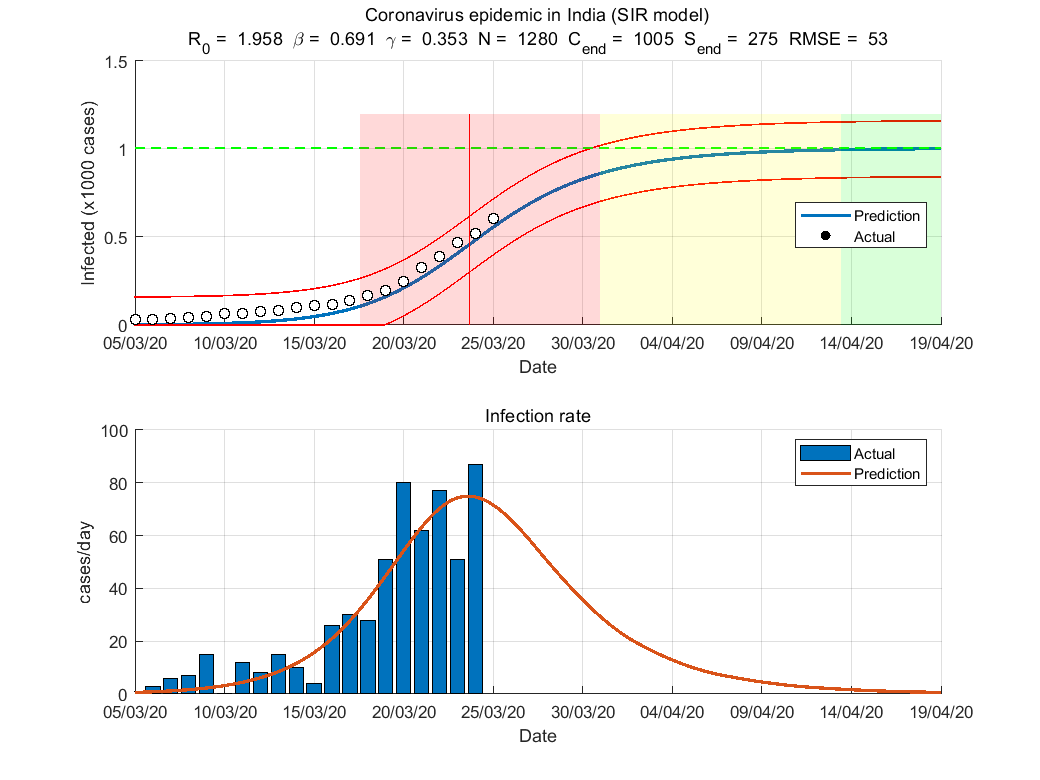

Epidemic modeling by susceptible-infected-recovered (SIR) model
  Country                       India
  Day                           23
Estimated the SIR model parameters
  Contact rate (beta)           0.691 (1/day)
  Removal rate (gamma)          0.353 (1/day)
  Population size (N)           1279
  Initial number of cases (I0)  0
Basic reproduction number (R0)  1.958
Final state
  Final number of cases         1004
  Final number of susceptibles  274
Daily forcast for 26-Mar-2020
  Total                         625
  Increase                      19
Estimated logistic model parameters
  Epidemic size (K)             840 (cases)
  Epidemic rate (r)             0.338353 (1/day)
  Initial doubling time         2 (day)
Estimated duration (days)
  Turning day                   21
  Acceleration   phase          6 (days)
  Deaceleration  phsee          7 (days)
  Total duration                13 (days)
Estimated datums
  Outbreak                      03-Mar-2020
  Start of acceleration   

aut = fitVirusCV19(@getDataIndia,'prn','on','nmax',1e5);